CREDITS

Made by Rahul S. Yerrabelli under Nai-Kong Cheung, MD, PhD at Memorial Sloan Kettering Cancer Center. This is part of the code accompanying the publication of "**Intra-Ommaya Compartmental Radioimmunotherapy using 131I-Omburtamab— Pharmacokinetic Modeling to Optimize Therapeutic Index**" (doi:10.1007/s00259-020-05050-z). See that paper and its supplement file for a greater description of the model and results.

FILE INFO

This file was created to analyze the saturation levels. It is presented as Figure 6 and Supplemental Figure 6.

Created Mar 26, 2020

Simulations.DefaultValues;

% Indices to access from returns or concentration_vals
cIBVi= 1; cINVi=2; cIBSi=3; cINSi=4; cIARVi=5; cIARSi=6; cINARVi=7; cINARSi=8;
cIRVi=9; cIRSi=10; cINRVi=11; cINRSi=12;


% Use an R0 that is 10x greater (and state so in the figure caption)
% so that AUC[C_IA] and AUC[C_IAR] are more easily plotted in one figure
%tumorload = 1.193674951486256e+12 / (6.022e23) *1000 %default
%tumorload = 1.193674951486256e+11 / (6.022e23) *1000 %10X less than default
%tumorload = 1.193674951486256e+13 / (6.022e23) *1000; %10X greater than default


% Set activities to run at
activities = sort([10:10:100]); %mCi



%determine which have letters. Default is no letter, then manually assign letters for some.
letters = cell(size(activities));
letters{activities==10}='A';
letters{activities==30}='B';
letters{activities==50}='C';
letters{activities==70}='D';

fontsize = 10;
axislinewidth = 1.5;
plotlinew = 1.5;
showtitles = false;
plot_while_analyzing = true;

Do computational analysis while also making the individual plots

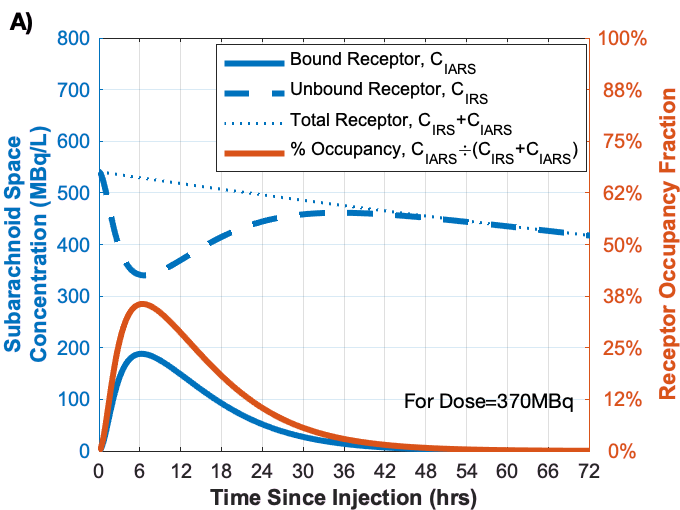

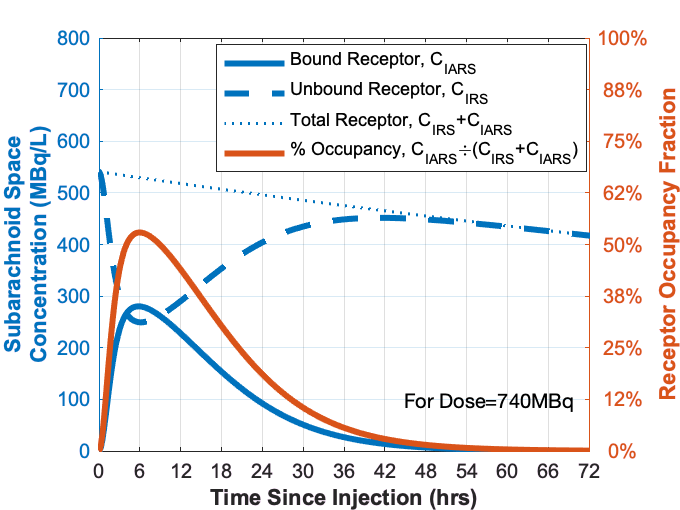

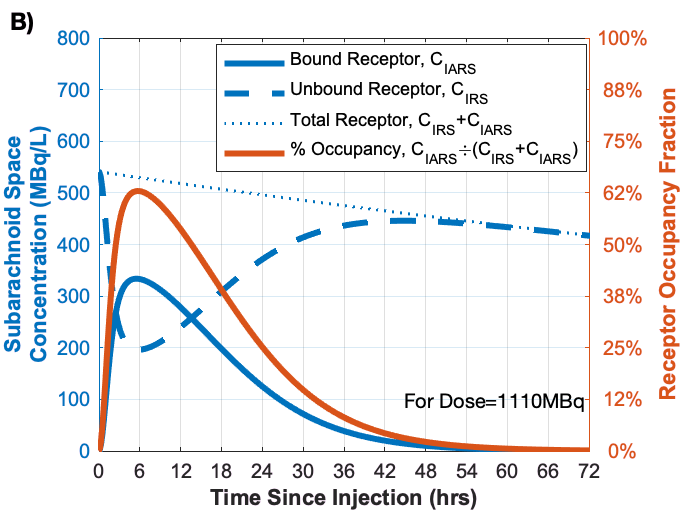

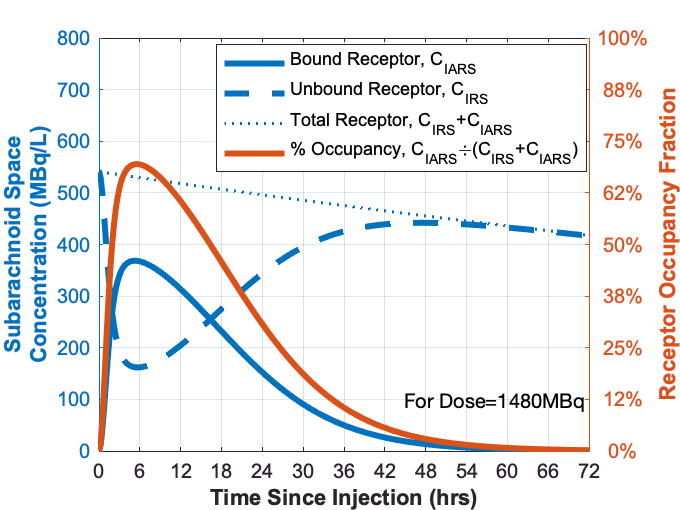

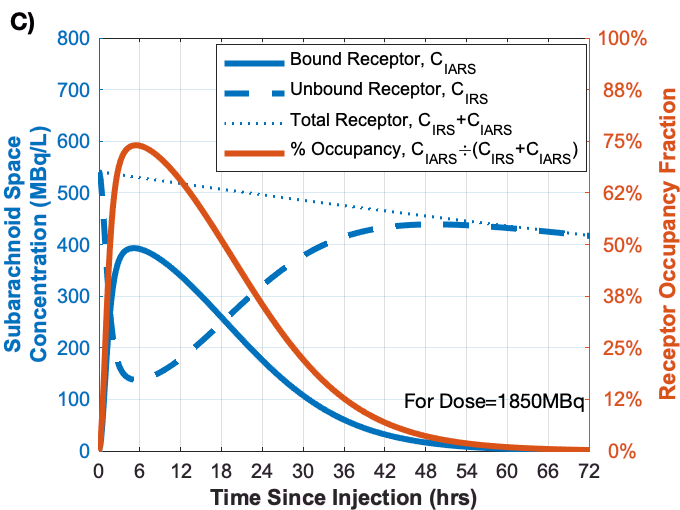

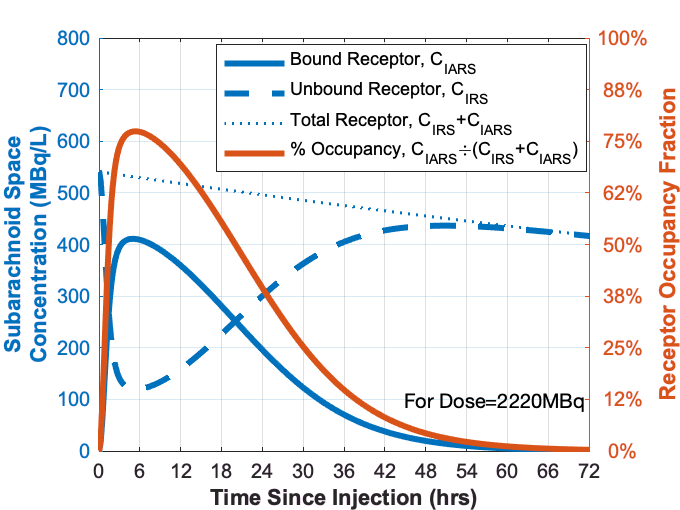

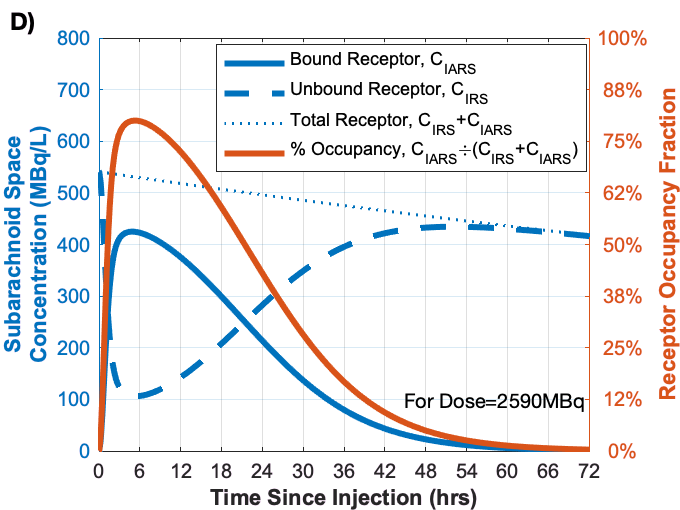

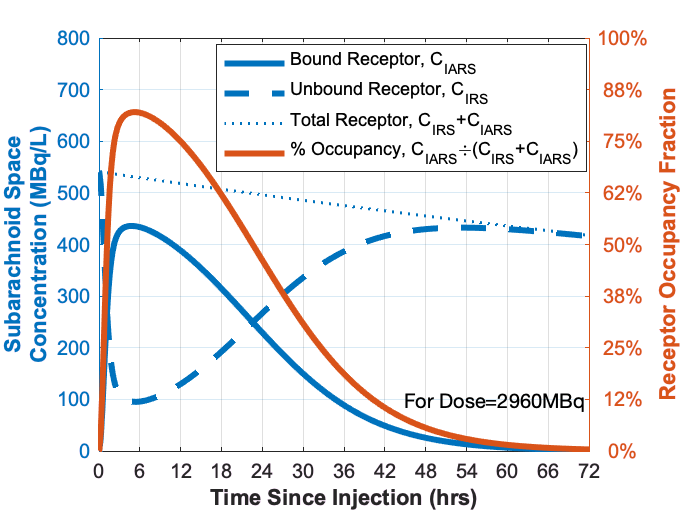

ys = zeros(4,length(activities));
concentration_vals = zeros(length(activities),length(time_values_needed),12);
for it = 1:length(activities)
    return_all = true;
    activityAdmin = activities(it);
    defined_params = [immunoreactivity, tumorload, perTV, perNB, ...
        kAR, k_AR, V, n, MM, cI0, t_half];
    [t, cIobs, AUC_cIAR, AUC_cIA, returns] = solveModel(activityAdmin,...
        Vv, CL, time_values_needed,defined_params,return_all);
    therap_ratio = [AUC_cIAR    AUC_cIA...
        (AUC_cIAR)/AUC_cIA (AUC_cIAR)/AUC_cIA*AUC_cIAR];
    %title(['Act. ' num2str(activityAdmin) ', AUC: ' num2str(AUC_cIA)]);
    
    ys(:,it) = therap_ratio;
    
    
    concentration_vals(it,:,:) = returns;  
    
    if plot_while_analyzing
        cIBV=returns(:,1); cINV=returns(:,2); cIBS=returns(:,3); cINS=returns(:,4); cIARV=returns(:,5); cIARS=returns(:,6); cINARV=returns(:,7); cINARS=returns(:,8);
        cIRV =returns(:,9); cIRS=returns(:,10); cINRV=returns(:,11); cINRS=returns(:,12);
        
        figure; hold on; grid on; box on;
        %Not factoring in ventricle components (cIARV, cIRV) bc they are 0
        %Multiply by 37 to convert mCi/L to MBq/L
        yyaxis left;
        plot(t/3600, cIARS*37,'-','LineWidth',plotlinew*2,'DisplayName','Bound Receptor, C_{IARS}');
        plot(t/3600, cIRS*37,'--','LineWidth',plotlinew*2,'DisplayName','Unbound Receptor, C_{IRS}');
        %Make below less thick
        plot(t/3600, (cIRS+cIARS)*37,':','LineWidth',plotlinew,'DisplayName','Total Receptor, C_{IRS}+C_{IARS}');
        ylabel({'Subarachnoid Space','Concentration (MBq/L)'},'FontWeight','bold');
        ylim([0 800]);
        yticks([0:100:800]);
    
        yyaxis right;
        plot(t/3600, cIARS./(cIRS+cIARS),'LineWidth',plotlinew*2,'DisplayName','% Occupancy, C_{IARS}\div(C_{IRS}+C_{IARS})');
        %set(gca,'yticklabel',num2str(get(gca,'ytick')'*100,'%.0f%%'));
        ylabel('Receptor Occupancy Fraction','FontWeight','bold');
        ylim([0 1]);
        yticks([0:0.125:1]); %Must specify ticks or might display wrong #s bc of % conversion and the later change of the gcf
        set(gca,'yticklabel',num2str(get(gca,'ytick')'*100,'%.0f%%'));
    
        xlim([0 72]); %hrs
        xticks([0:6:72]); %hrs
        xlabel('Time Since Injection (hrs)','FontWeight','bold');
        legend('show');
        legend({},'Position',[0.59 0.79 0 0],'Units','normalized')
        if showtitles
            title(['Receptor Occupancy for ' num2str(activityAdmin*37) 'MBq, R_0=' num2str(tumorload,'%0.1e')]);
        end
        
        %annotation('textbox',[0.45, 0, 0.6, 0.2],'String',['For Dose=' num2str(activityAdmin*37) 'MBq, R_0=' num2str(tumorload,'%0.1e') 'M'],'FitBoxToText','on','EdgeColor','none ');
        %annotation('textbox',[0.13, 0.18, 0, 0],'String',['For Dose=' num2str(activityAdmin*37) 'MBq'],'FitBoxToText','on','EdgeColor','none ');
        annotation('textbox',[0.58, 0.25, 0, 0],'String',['For Dose=' num2str(activityAdmin*37) 'MBq'],'FitBoxToText','on','EdgeColor','none ');
        
        if ischar(letters{it})
            %Add A), B), C) etc text here
            letter=letters{it};
            xloc=0; yloc = 1;
            if (yloc >= 0) && (yloc <= 1) && (xloc >= 0) && (xloc <= 1) %otherwise will throw error
                %Letter should be in 12pt helvetica font, regardless of the font of the rest of the figures, per JNM
                annotation('textbox', [xloc, yloc, 0, 0], 'string', strcat(letter,')'),'FontSize',12,'fontname','helvetica', 'FontWeight', 'bold','tag','FigurePartLetter');
            end
        end
        
        %set(gca,'LineWidth',axislinewidth*resratio); %don't do this so that the grids aren't too thick
        set(gca,'FontSize',fontsize, 'FontName','Arial'); %Arial for figure text, Helvetica for labels
        set(gcf,'PaperPositionMode','Manual');
        set(gcf,'PaperUnits','centimeters','PaperPosition', [0 0 12 9]); %for saving the file
        set(gcf,'Units','centimeters','Position', [0 0 12 9]); %for showing up in the mlx file
        print(['Figures/Saturation/Receptor Occupancy for ' num2str(activityAdmin*37) 'MBq and R_0=' num2str(tumorload,'%0.1e') 'M.png'], '-dpng', '-r600'); %<-Save as PNG with certain DPI
        print(['Figures/Saturation/Receptor Occupancy for ' num2str(activityAdmin*37) 'MBq and R_0=' num2str(tumorload,'%0.1e') 'M.tif'], '-dtiff', '-r600'); %<-Save as TIFF with certain DPI
        print(['Figures/Saturation/Receptor Occupancy for ' num2str(activityAdmin*37) 'MBq and R_0=' num2str(tumorload,'%0.1e') 'M 300p.tif'], '-dtiff', '-r300'); %<-Save as TIFF with certain DPI
    end
end

Not factoring in ventricle components (cIARV, cIRV) bc they are 0

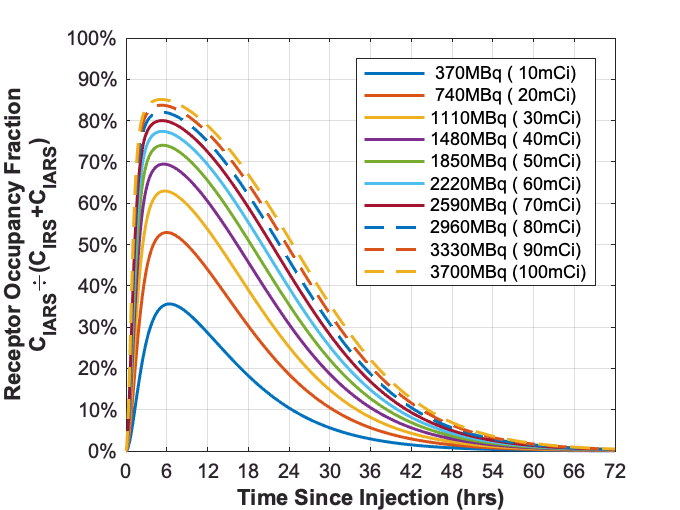

figure; grid on; hold on; box on;
occupancy_fraction = concentration_vals(:,:,cIARSi) ./ (concentration_vals(:,:,cIARSi) + concentration_vals(:,:,cIRSi));
%Split into line (-) and dashed (--) bc only 7 unque default colors
plot(t/3600, occupancy_fraction(1:7,:)','-','LineWidth',plotlinew);
plot(t/3600, occupancy_fraction(8:end,:)','--','LineWidth',plotlinew);
legendarr = cellstr( strcat(num2str(activities'*37),'MBq (', num2str(activities'), 'mCi)') );



xlim([0 72]); %hrs
xticks([0:6:72]); %hrs
xlabel('Time Since Injection (hrs)','FontWeight','bold');
ylim([0 1]); 
yticks([0:0.1:1]) %Must specify ticks or might display wrong #s bc of % conversion and the later change of the gcf
set(gca,'yticklabel',num2str(get(gca,'ytick')'*100,'%.0f%%'));
ylabel({'Receptor Occupancy Fraction', 'C_{IARS}\div(C_{IRS}+C_{IARS})'},'FontWeight','bold');
legend(legendarr)

if showtitles
    title(['Receptor Occupancy for R_0=' num2str(tumorload,'%0.1e') 'M']);
end

%set(gca,'LineWidth',axislinewidth*resratio); %don't do this so that the grids aren't too thick
set(gca,'FontSize',fontsize, 'FontName','Arial'); %Arial for figure text, Helvetica for labels
set(gcf,'PaperPositionMode','Manual');
set(gcf,'PaperUnits','centimeters','PaperPosition', [0 0 12 9]); %for saving the file
set(gcf,'Units','centimeters','Position', [0 0 12 9]); %for showing up in the mlx file
print(['Figures/Saturation/Receptor Occupancy across Activities for R_0=' num2str(tumorload,'%0.1e') 'M.png'], '-dpng', '-r600'); %<-Save as PNG with certain DPI
print(['Figures/Saturation/Receptor Occupancy across Activities for R_0=' num2str(tumorload,'%0.1e') 'M.tif'], '-dtiff', '-r600'); %<-Save as TIFF with certain DPI
print(['Figures/Saturation/Receptor Occupancy across Activities for R_0=' num2str(tumorload,'%0.1e') 'M 300p.tif'], '-dtiff', '-r300'); %<-Save as TIFF with certain DPI